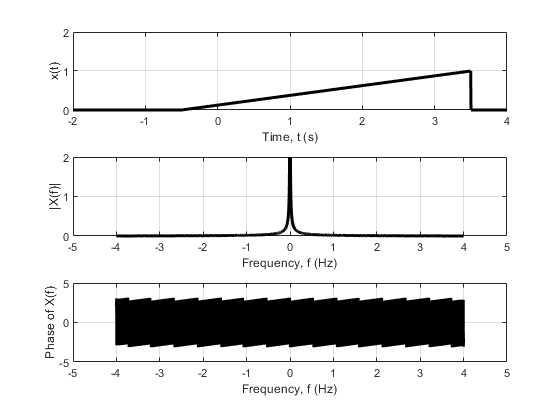

% Program to demonstrate approximating the CTFT of t(1-t)*rect(t-1/2) 
% by sampling it 32 times in the time interval 0 <= t < 2 seconds
% and using the DFT. 
N = 128 ;                                               % Sample 32 times
Ts = 2/N ;                                              % Sample for two seconds
                                                        % and set sampling interval
f=1/T;                                                  % Frecuencia
fs=(1/T):1/T:(N/T);                                     % Normalizacion vector de Frecuencia
np=T*0.001;                                             % Espacio numerico definido en el periodo de la funcion (np=Numero de muestras en un periodo)
t=-(2*T):np:(2*T);                                      % Limites del espacio numerico (eje de abscisas ¨tiempo¨)
%fs = 1/Ts ;                                            % Set sampling rate 
df = fs/N ;                                             % Set frequency-domain resolution
n = [0:N-1];                                            % Vector of 32 time indices 
%t = Ts*n ;                                             % Vector of times
x = (t/4 + 1/8).*rectangularPulse(-1/2,7/2,t);          % Vector of 32 x(t) function values 
X = fftshift(Ts*fft(x)) ;                               % Vector of 32 approx X(f) CTFT
                                                        % values
k = [-N/2:N/2-1];                                       % Vector of 16 frequency indices

% Graph the results 
subplot(3,1,1) ;
p = plot(t,x,'k') ; set(p,'LineWidth',2) ; grid on ; 
xlabel('Time, t (s)') ; ylabel('x(t)') ; axis([-2 4 0 2])
subplot(3,1,2) ;
p = plot(t,abs(X),'k') ; set(p,'LineWidth',2) ; grid on;
xlabel('Frequency, f (Hz)') ; ylabel('|X(f)|') ; axis([-5 5 0 2])
subplot(3,1,3) ;
p = plot(t,angle(X),'k') ; set(p,'LineWidth',2) ; grid on ;
xlabel('Frequency, f (Hz)') ; ylabel('Phase of X(f)') ; axis([-5 5 -5 5])